Параметры источника питания, нагрузки, трехфазного инвертора и его блока управления задаются в соответствии с вариантом.

DC_voltage = 1900;
U_fd = 0.8;
U_f = 1.6;
R_on = 0.001;
freq_mod = 100;
Kratnost_NesMod = 20;
koef_mod1 = 0.5;
koef_mod2 = 1.5;
Table_Res = 1:10;

L_n = zeros(1, 10);
I_1 = zeros(1, 10);
U_n1 = zeros(1, 10);
I_n1 = zeros(1, 10);
phi_U = zeros(1, 10);
phi_I = zeros(1, 10);
I_T0 = zeros(1, 10);
I_TRMS = zeros(1, 10);

Моделирование

koef_mod = koef_mod1;
for i = Table_Res
    Nagr.Res = Table_Res(i);
    Nagr.Ind = 0.5 * Nagr.Res / freq_mod;
    sim("lr6.slx");
    L_n(i) = Nagr.Ind;
    I_1(i) = DCsource_current(end);
    U_n1(i) = Volt_load(end);
    I_n1(i) = Current_load(end);
    phi_U(i) = phi_Volt_load(end);
    phi_I(i) = phi_Current_load(end);
    I_T0(i) = Current_IGBT_mean(end);
    I_TRMS(i) = Current_IGBT_RMS(end);
end

Вычисления

Сдвиг по фазе между первой гармоникой тока и напряжения на нагрузке рассчитывается по формуле


$$\phi_н =\phi_U -\phi_I$$


Полная и активная мощность по первой гармонике в нагрузке определяется по выражениям


$$S_н \left(1\right)=\frac{3U_н \left(1\right)I_н \left(1\right)}{2}$$



$$P_н \left(1\right)=\frac{3U_н \left(1\right)I_н \left(1\right)\cos_{\phi_н } }{2}$$


Мощность, потребляемая от источника питания, определяется по выражению


$$P_1 =U_1 I_1$$


Потери в силовом полупроводниковом модуле определяются по формуле


$$P_T =\left\lbrack {\mathrm{mV}}_f +\left(1-m\right)V_{\mathrm{fd}} \;\frac{\cos \phi_н -1}{\cos \phi_н +1}\right\rbrack I_{\mathrm{T0}} +R_{\mathrm{on}} {\left\lbrack I_{\mathrm{TRMS}} \right\rbrack }^2$$


Коэффициент модуляции $m=\frac{U_{\mathrm{мод}} }{U_{\mathrm{ГПН}} }$

phi_n1 = phi_U - phi_I;
S_n1 = 3 * U_n1 .* I_n1 / 2;
P_n1 = 3 * U_n1 .* I_n1 .* cosd(phi_n1) / 2;
P_1 = DC_voltage * I_1;
m = koef_mod1 / 1;
P_T = (m*U_f + (1-m)*U_fd * (cosd(phi_n1)-1)/(cosd(phi_n1)-1))...
    .* I_T0 + R_on*I_TRMS.^2;

Формирование таблицы измерений и вычислений

Table1 = [Table_Res; L_n; I_1; U_n1; I_n1; phi_U; phi_I; I_T0; I_TRMS; phi_n1; S_n1; P_n1; P_T; P_1];
T11 = array2table(Table1(1:2,:).');
T12 = array2table(Table1(3:9,:).');
T13 = array2table(Table1(10:14,:).');
T11.Properties.VariableNames = ["Rn", "Ln"];
T12.Properties.VariableNames = ["I(1)", "Un(1)", "In(1)", "phi_U", "phi_I", "Iт0", "Iт(RMS)"];
T13.Properties.VariableNames = ["phi_n(1)", "Sn(1)", "Pn(1)", "Pт", "P(1)"];

Данные

disp(T11);

    Rn     Ln  
    __    _____

     1    0.005
     2     0.01
     3    0.015
     4     0.02
     5    0.025
     6     0.03
     7    0.035
     8     0.04
     9    0.045
    10     0.05



Измерения

disp(T12);

     I(1)     Un(1)     In(1)       phi_U       phi_I      Iт0      Iт(RMS)
    ______    ______    ______    _________    _______    ______    _______

    16.447    474.16    143.82     0.016559    -72.327    45.842    71.948 
    8.2486    474.18    71.913    0.0082798    -72.335    22.923    35.976 
    5.5173    474.18    47.943    0.0055202    -72.338    15.282    23.985 
     4.152    474.19    35.957    0.0041403    -72.339    11.462    17.989 
    3.3328    474.19    28.766    0.0033123     -72.34    9.1699    14.392 
    2.7868    474.19    23.972    0.0027603     -72.34    7.6418    11.993 
    2.3968    474.19    20.547     0.002366    -72.341    6.5502     10.28 
    2.1042    474.19    17.979    0.0020703    -72.341    5.7316    8.9955 
 

Вычисления

disp(T13);

    phi_n(1)      Sn(1)       Pn(1)       Pт       P(1) 
    ________    __________    ______    ______    ______

     72.343     1.0229e+05     31026    60.187     31249
     72.343          51149     15514    28.802     15672
     72.343          34100     10343    18.914     10483
     72.343          25576    7757.5    14.078    7888.7
     72.343          20461      6206    11.211    6332.4
     72.343          17051    5171.7     9.314    5294.9
     72.343          14615    4432.9     7.966    4553.8
     72.343          12788    3878.8    6.9588    3998.1
     72.343          11367    3447.9    6.1777    3565.8
     72.343          10231    3103.1    5.5543      3220



Строим характеристики по результатам исследований

Внешняя (нагрузочная) характеристика инвертора

figure;
plot(I_n1, U_n1);
xlabel("I_н, А");
ylabel("U_н, В");
ylim([0 max(U_n1)*1.1]);
grid on;

Энергетические характеристики

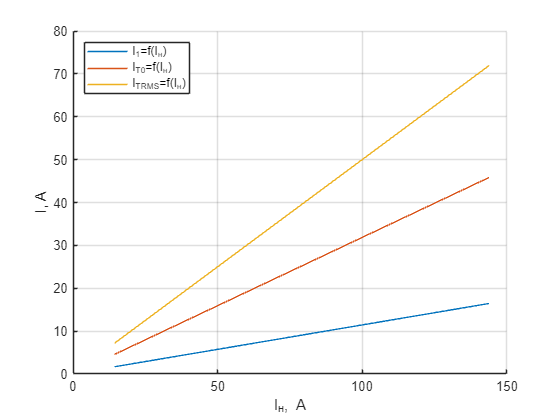

figure;
hold on;
plot(I_n1, I_1);
plot(I_n1, I_T0);
plot(I_n1, I_TRMS);
hold off;
xlabel("I_н, А");
ylabel("I, A");
legend("I_1=f(I_н)", "I_{T0}=f(I_н)", "I_{TRMS}=f(I_н)", "Location","northwest");
grid on;

Энергетические характеристики инвертора

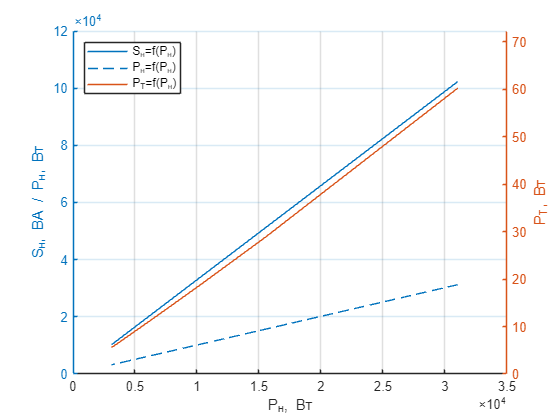

figure;
hold on;
yyaxis left;
plot(P_n1, S_n1);
plot(P_n1, P_1);
xlabel("P_н, Вт");
ylabel("S_н, ВA / P_н, Вт");
yyaxis right;
plot(P_n1, P_T);
ylabel("P_T, Вт");
ylim([0 1.2*max(P_T)])
hold off;
legend("S_н=f(P_н)", "P_н=f(P_н)", "P_T=f(P_н)", "Location","northwest");
grid on;

Исследование регулировочной характеристики инвертора осуществляется на модели при одном значении сопротивления нагрузки и изменении амплитуды модулирующего напряжения от 0 до 1 В с шагом 0,2 В.

Nagr.Res = 1; % Заданное сопротивление
Nagr.Ind = 0.5 * Nagr.Res / freq_mod;
table_m = 0:0.2:1;
table_Un = [];
for i = table_m
    koef_mod = i;
    sim("lr6.slx");
    table_Un(end+1) = Volt_load(end);
end

T2 = table(table_m.', round(table_Un, 1).', VariableName = ["m", "Un, В"]);
disp(T2);

     m     Un, В
    ___    _____

      0        0
    0.2    189.7
    0.4    379.3
    0.6      569
    0.8    758.6
      1    948.3



По данным таблицы строим регулировочную характеристику

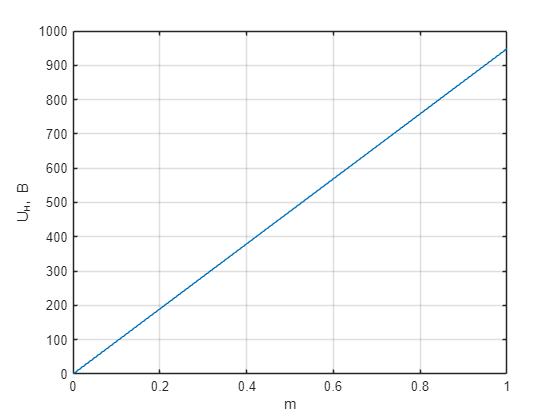

figure
plot(table_m, table_Un);
grid on;
ylabel("U_н, В");
xlabel("m");

Исследование спектрального состава напряжения и тока нагрузки инвертора осуществляется при двух значениях коэффициента модуляции m>1 и m<1

koef_mod = koef_mod1;
table3_m = [];
num_harm = [];
table3_Un1 = [];
amp2fund_U = [];
table3_In1 = [];
amp2fund_I = [];
table3_Unv = [];
table3_Inv = [];
freq = 1:5000;
sim("lr6.slx");

Спектральный состав тока нагрузки инвертора при m<1

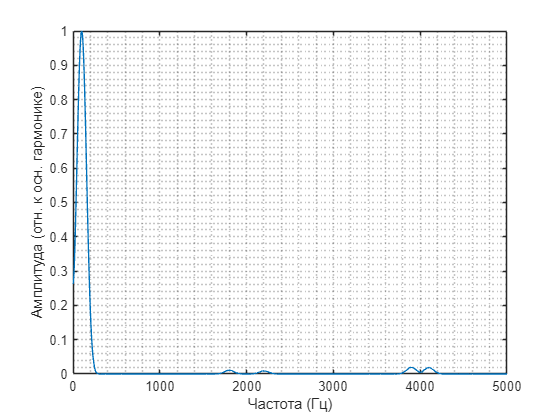

[p_I, f] = pspectrum(In_Un.signals(1).values,100000,'power', 'FrequencyLimits', [0 5000]);
p_I = sqrt(p_I) / max(sqrt(p_I));
plot(f, p_I);
ylabel('Амплитуда (отн. к осн. гармонике)');
xlabel('Частота (Гц)');
grid minor;

Спектральный состав напряжения на нагрузке инвертора при m<1

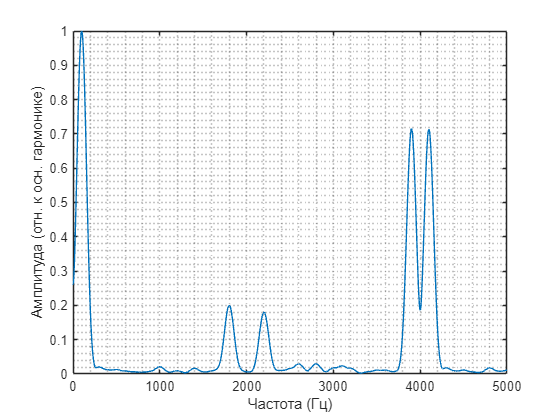

[p_U, f] = pspectrum(In_Un.signals(2).values,100000,'power', 'FrequencyLimits', [0 5000]);
p_U = sqrt(p_U) / max(sqrt(p_U));
plot(f, p_U);
ylabel('Амплитуда (отн. к осн. гармонике)');
xlabel('Частота (Гц)');
grid minor;

Расчёт пиковых значений спектограммы

ampU = interp1(f, p_U, freq);
ampI = interp1(f, p_I, freq);
[peaks, locs] = findpeaks(ampU, "MinPeakHeight", 0.1);
table3_m(end+1:end+length(peaks)) = ones(1,length(peaks)) * koef_mod;
num_harm(end+1:end+length(peaks)) = locs/freq_mod;
table3_Un1(end+1:end+length(peaks)) = ones(1,length(peaks)) * Volt_load(end);
amp2fund_U(end+1:end+length(peaks)) = ampU(locs);
table3_In1(end+1:end+length(peaks)) = ones(1,length(peaks)) * Current_load(end);
amp2fund_I(end+1:end+length(peaks)) = ampI(locs);
table3_Inv(end+1:end+length(peaks)) = ampI(locs) .* Current_load(end);
table3_Unv(end+1:end+length(peaks)) = ampU(locs) .* Volt_load(end);

koef_mod = koef_mod2;
sim("lr6.slx");

Спектральный состав тока нагрузки инвертора при m>1

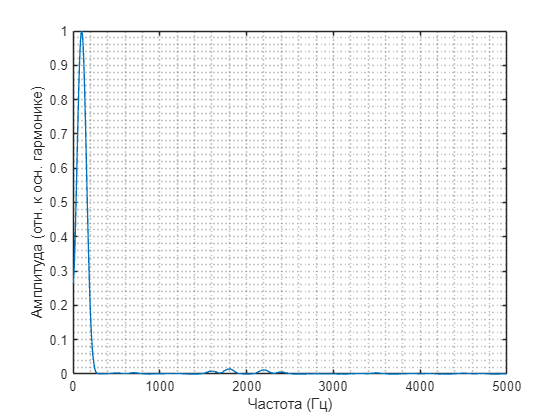

[p_I, f] = pspectrum(In_Un.signals(1).values,100000,'power', 'FrequencyLimits', [0 5000]); % Вычисление спектра
p_I = sqrt(p_I) / max(sqrt(p_I));                          % Нормализация по максимуму и преведение мощности к амплитуде
plot(f, p_I);
ylabel('Амплитуда (отн. к осн. гармонике)');
xlabel('Частота (Гц)');
grid minor;

Спектральный состав напряжения на нагрузке инвертора при m>1

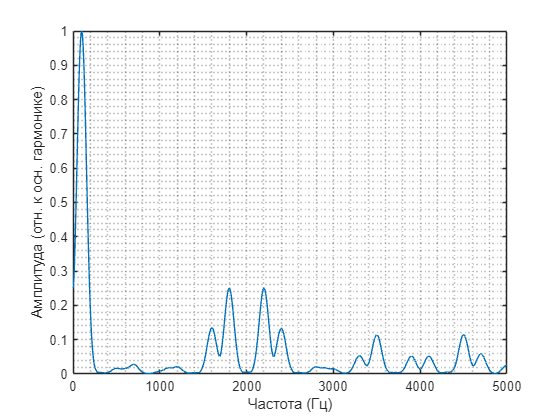

[p_U, f] = pspectrum(In_Un.signals(2).values,100000,'power', 'FrequencyLimits', [0 5000], 'Leakage', 0.00004); % Вычисление спектра
p_U = sqrt(p_U) / max(sqrt(p_U));                          % Нормализация по максимуму и преведение мощности к амплитуде
plot(f, p_U);
ylabel('Амплитуда (отн. к осн. гармонике)');
xlabel('Частота (Гц)');
grid minor;

Расчёт пиковых значений спектограммы

ampU = interp1(f, p_U, freq);
ampI = interp1(f, p_I, freq);
[peaks, locs] = findpeaks(ampU, "MinPeakHeight", 0.1);
table3_m(end+1:end+length(peaks)) = ones(1,length(peaks)) * koef_mod;
num_harm(end+1:end+length(peaks)) = locs/freq_mod;
table3_Un1(end+1:end+length(peaks)) = ones(1,length(peaks)) * Volt_load(end);
amp2fund_U(end+1:end+length(peaks)) = ampU(locs);
table3_In1(end+1:end+length(peaks)) = ones(1,length(peaks)) * Current_load(end);
amp2fund_I(end+1:end+length(peaks)) = ampI(locs);
table3_Inv(end+1:end+length(peaks)) = ampI(locs) .* Current_load(end);
table3_Unv(end+1:end+length(peaks)) = ampU(locs) .* Volt_load(end);

Таблица 3 – Исследование спектра сигналов тока и напряжения

Table3 = [table3_m; num_harm; table3_Un1; 100*round(amp2fund_U, 4); table3_In1; 100*round(amp2fund_I, 4); table3_Unv; table3_Inv];
T3 = array2table(Table3.', VariableNames= ["m", "№ гарм.", "Uн(1), В", "отн. U, %", "Iн(1), А", "отн. I, %", "Uн(v), В", "Iн(v), А"]);
disp(T3);

     m     № гарм.    Uн(1), В    отн. U, %    Iн(1), А    отн. I, %    Uн(v), В    Iн(v), А
    ___    _______    ________    _________    ________    _________    ________    ________

    0.5       1        474.16         100       143.82        100        474.15      143.82 
    0.5      18        474.16       20.04       143.82       1.09        95.008      1.5656 
    0.5      22        474.16       18.03       143.82       0.89        85.509       1.281 
    0.5      39        474.16       71.48       143.82       1.94        338.94      2.7958 
    0.5      41        474.16       71.34       143.82       1.85        338.28      2.6573 
    1.5       1        1111.3         100       337.07        100        111